# Probability

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Probability');

## Sampling from a Normal Distribution (N=5)

norm0 = normrnd(10,2,[1 5])

norm0 =     6.8137   11.2134    9.1026    7.2613   12.5429


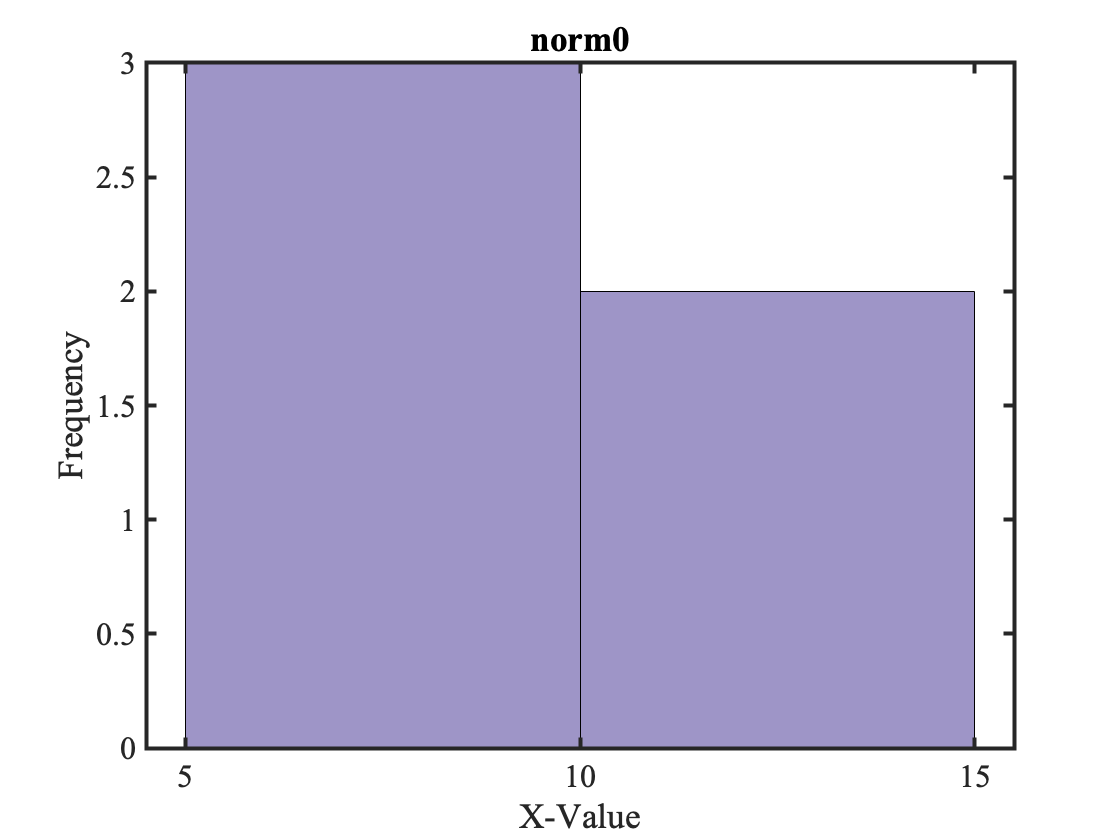

figure();
histogram(norm0);
xlabel('X-Value');
ylabel('Frequency');
title('norm0');
auto_save('normN5')

## Sampling from a Normal Distribution (N = 1000)

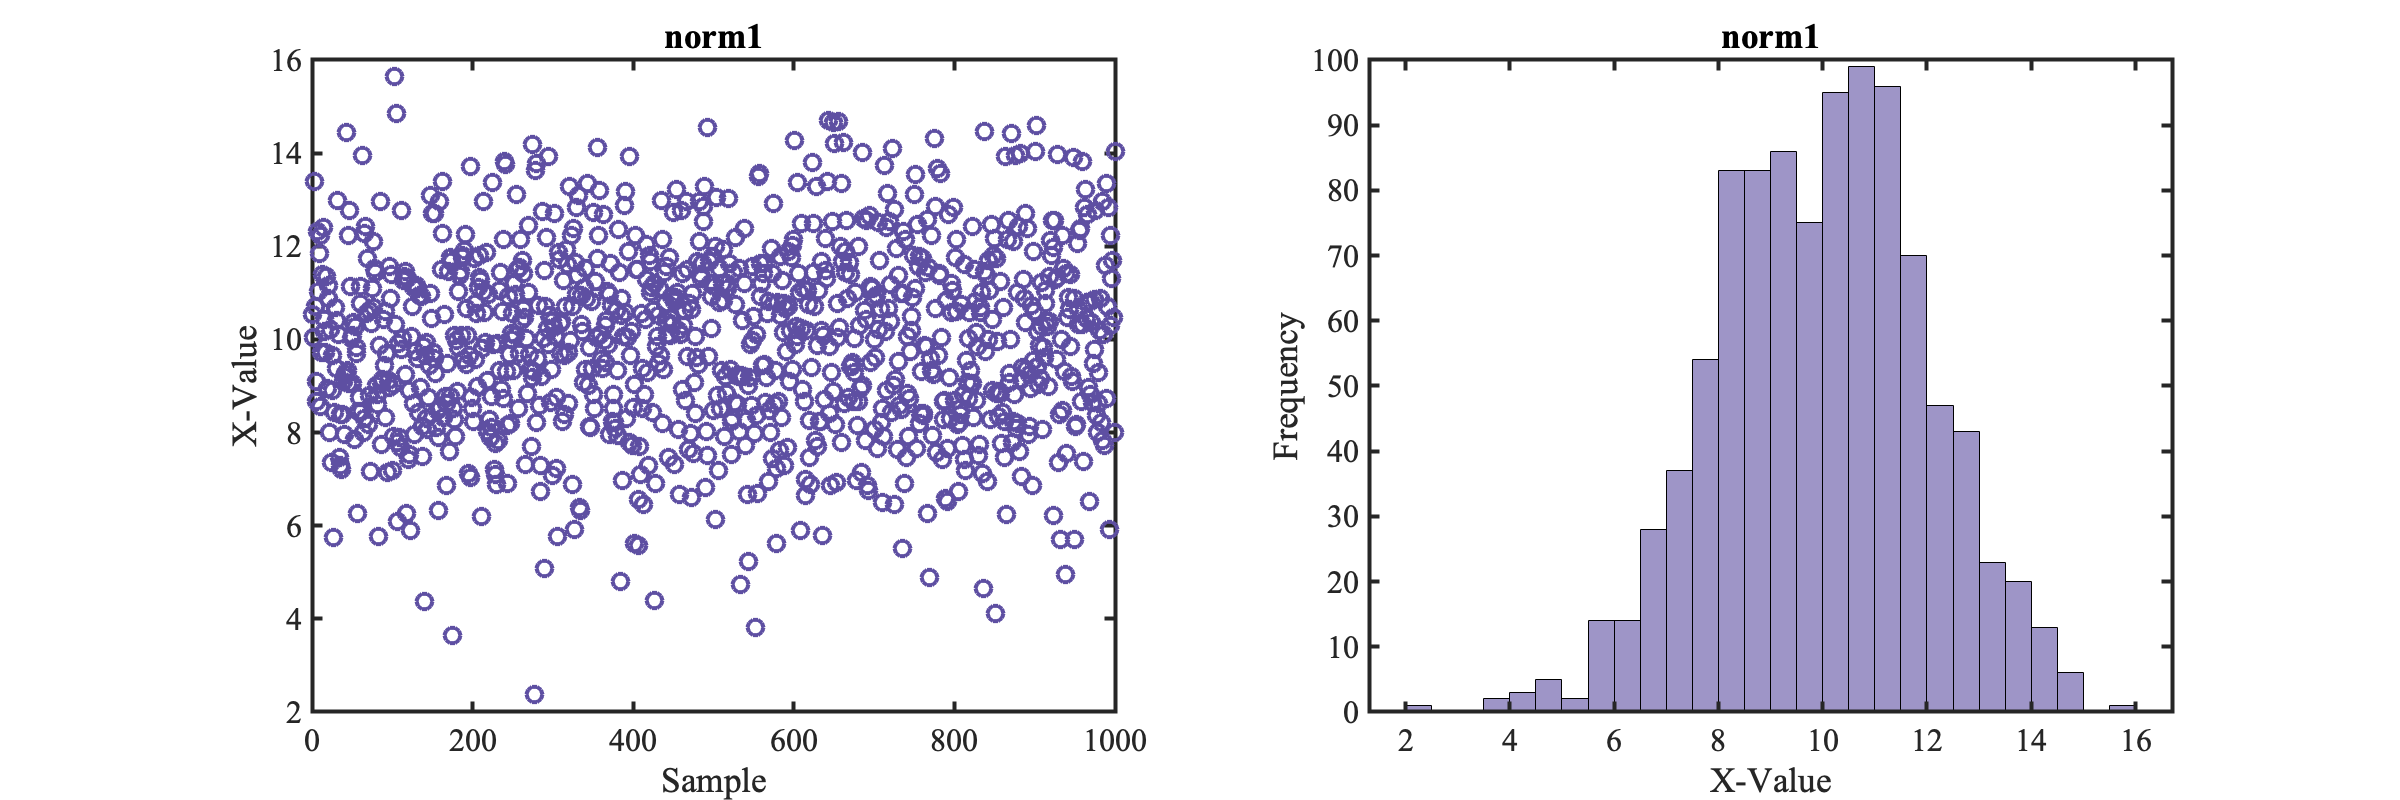

norm1 = normrnd(10, 2, [1 1000]);

figure('position', [300 300 1200 400]);
subplot(1,2,1);
plot(norm1, 'o', 'markersize', 8);
xlabel('Sample'); 
ylabel('X-Value'); 
title('norm1');
subplot(1,2,2);
histogram(norm1);
xlabel('X-Value');
ylabel('Frequency');
title('norm1');
auto_save('normN1000')

## Summary of Sampled Data

min(norm1)

ans = 2.3854

quantile(norm1, 0.25)

ans = 8.5232

median(norm1)

ans = 10.0530

mean(norm1)

ans = 9.9712

quantile(norm1, 0.75)

ans = 11.3926

max(norm1)

ans = 15.6420

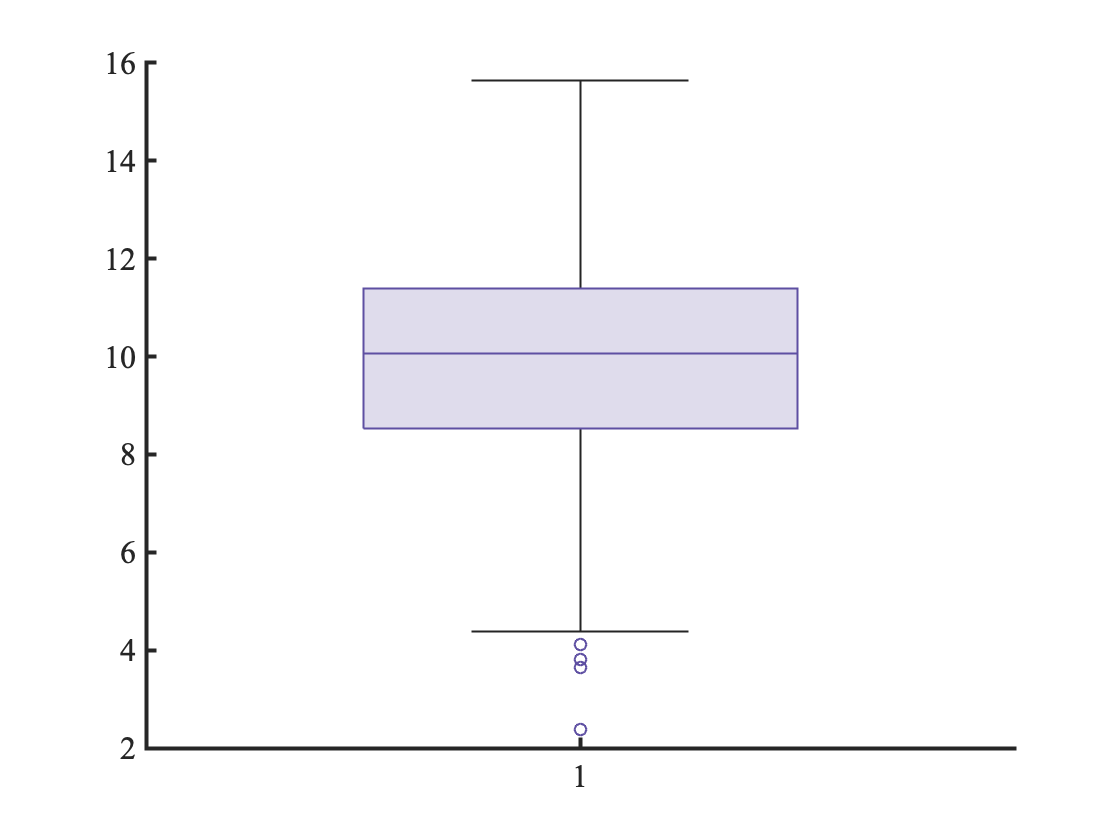


figure();
boxchart(norm1)
auto_save('boxplot')

## Fit the Data

FIT = fitdist(norm1', 'normal')

FIT =   NormalDistribution

  Normal distribution
       mu = 9.97119   [9.84602, 10.0964]
    sigma =   2.017   [1.93231, 2.10951]


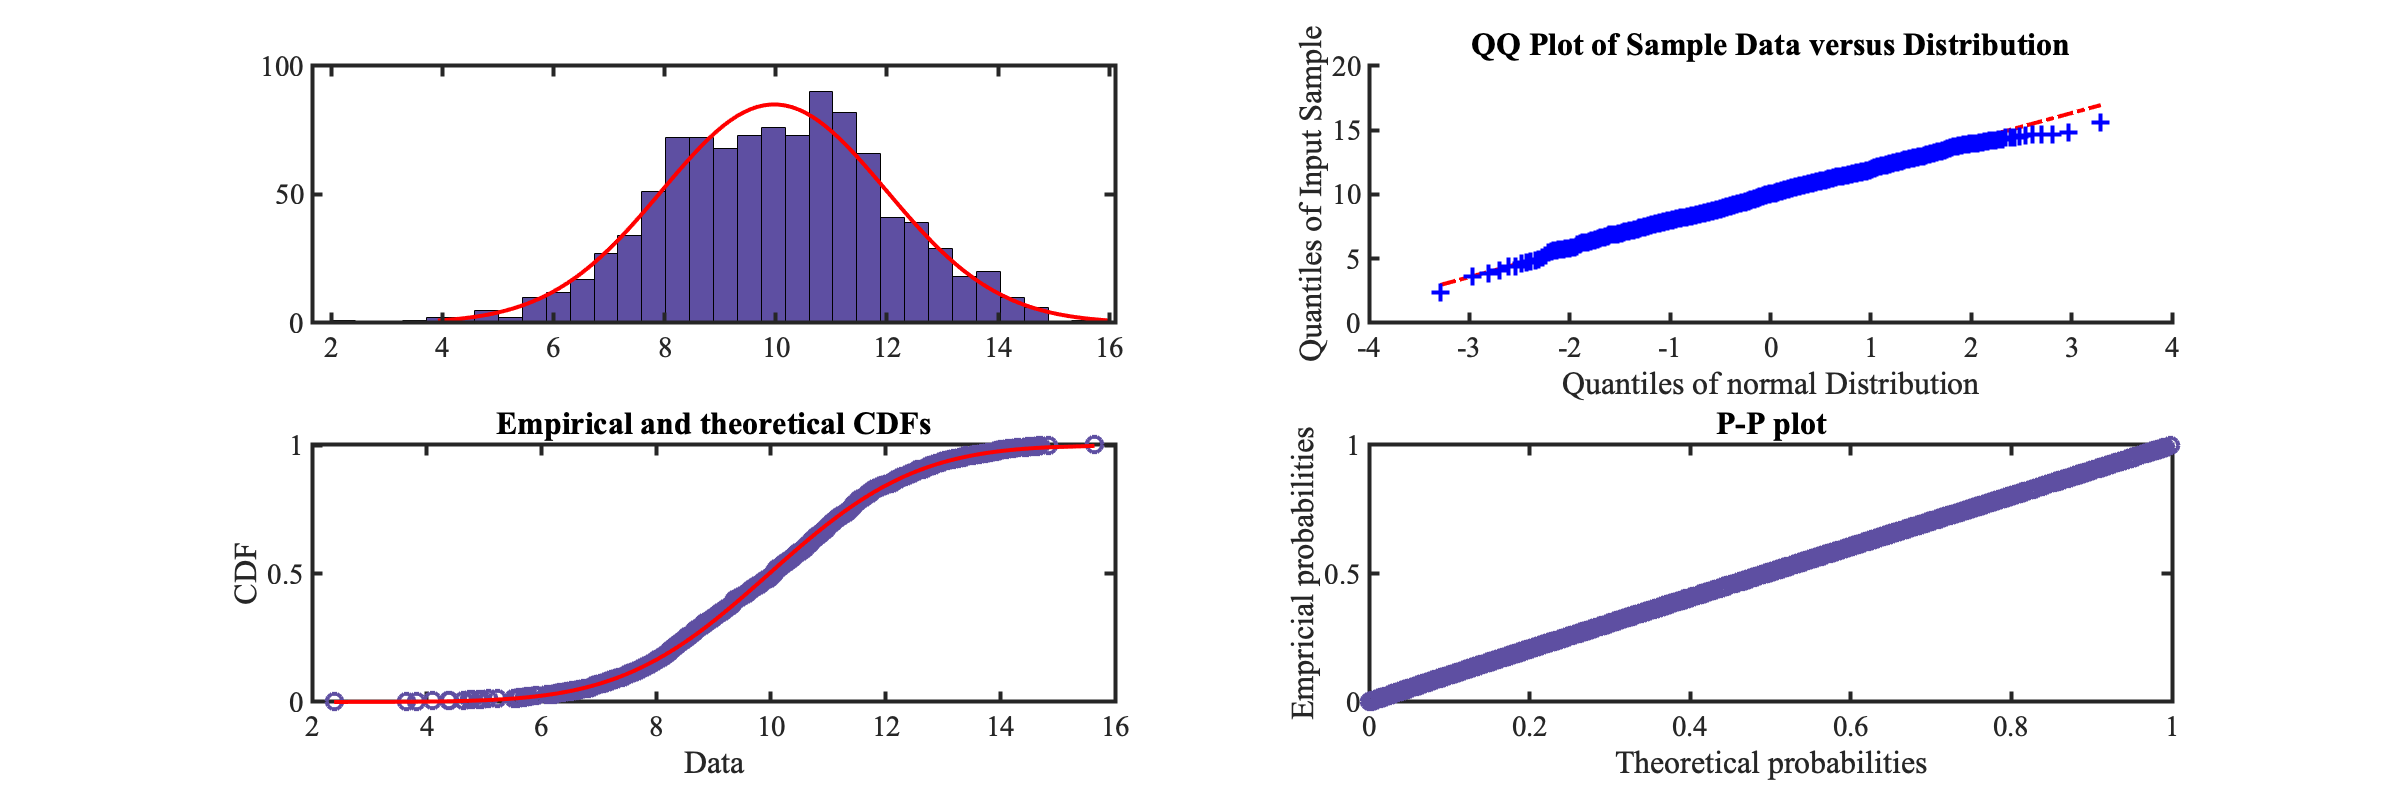


figure('position', [300 300 1200 400]);
subplot(2,2,1);
histfit(norm1);
subplot(2,2,2)
QQ = qqplot(norm1, makedist('normal'));
set(QQ(1), 'markersize', 8);
subplot(2,2,3);
x = sort(norm1);
y = 1 * (1:length(norm1)) / (length(norm1) - 1);
plot(x,y,'o', 'markersize', 8);
hold on 
y = normcdf(x, FIT.mu, FIT.sigma);
plot(x,y,'r-')
xlabel('Data') 
ylabel('CDF')
title('Empirical and theoretical CDFs')
subplot(2,2,4)
theoretical_prob = normcdf(norm1, 10, 2);
empirical_prob = normcdf(norm1, FIT.mu, FIT.sigma);
plot(theoretical_prob, empirical_prob,'o', 'markersize', 8)
xlabel('Theoretical probabilities')
ylabel('Empricial probabilities')
title('P-P plot');
auto_save('fitdata')

## Testing Normality - Shapiro-Wilk Test (Univariate)

[h, p, w] = swtest(norm1)

h = logical
   0

p = 0.0724

w = 0.9971

## Testing Normality - Beta Distribution

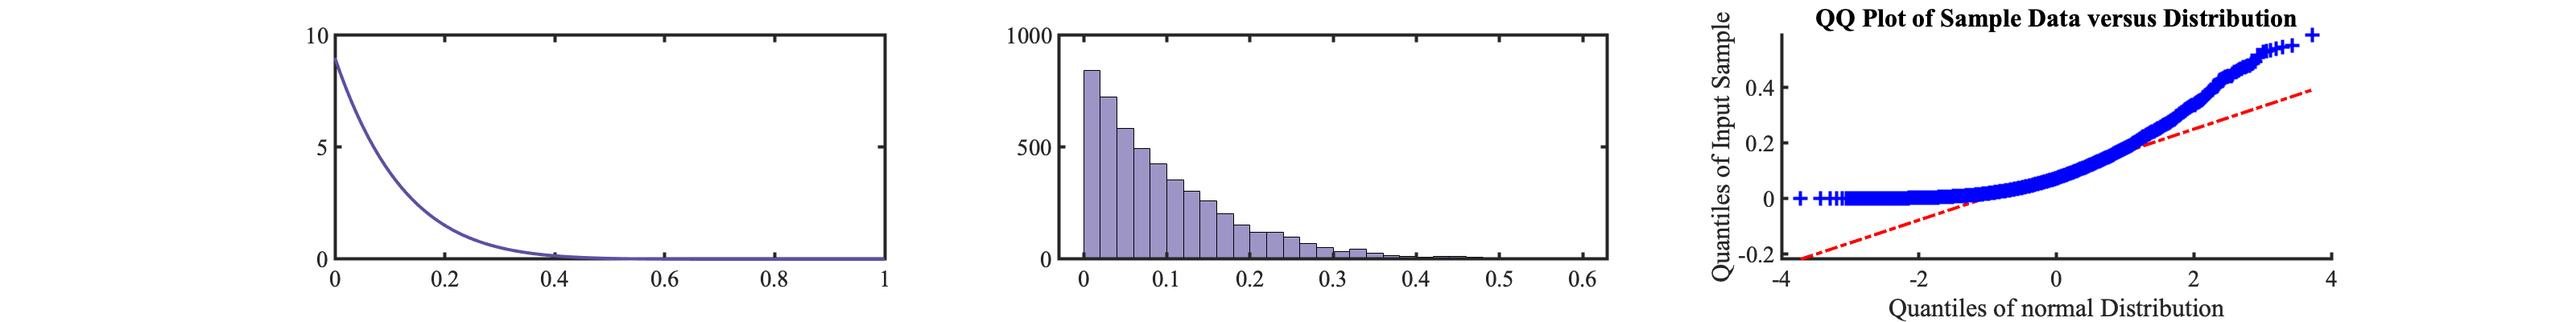

beta0 = betarnd(1, 9, [5000 1]);
p = linspace(0,1,100);
figure('position', [300 300 1600 200]);
subplot(1,3,1);
plot(p, betapdf(p, 1, 9));
subplot(1,3,2);
histogram(beta0)
subplot(1,3,3);
QQ = qqplot(beta0, makedist('normal'));
set(QQ(1), 'markersize', 8);
auto_save('betanormal')

[h, p, w] = swtest(beta0)

h = logical
   1

p = 0

w = 0.8665

## Sample from a Bivariate Normal

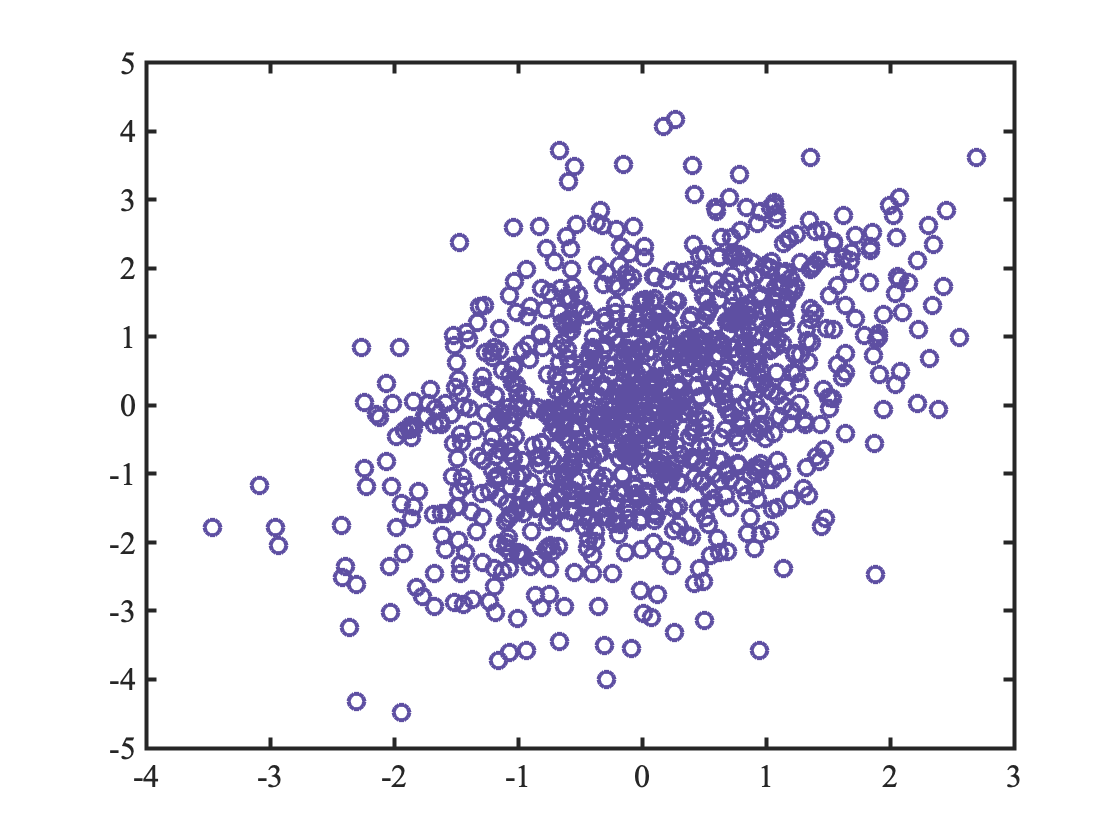

my_n1 = 1000;
my_mu1 = [0; 0];
my_Sigma1 = [1, 0.6; 0.6, 2];
binorm = mvnrnd(my_mu1, my_Sigma1, my_n1);
figure();
plot(binorm(:,1), binorm(:,2), 'o', 'markersize', 8);
auto_save('binorm')

## Confidence Ellipse

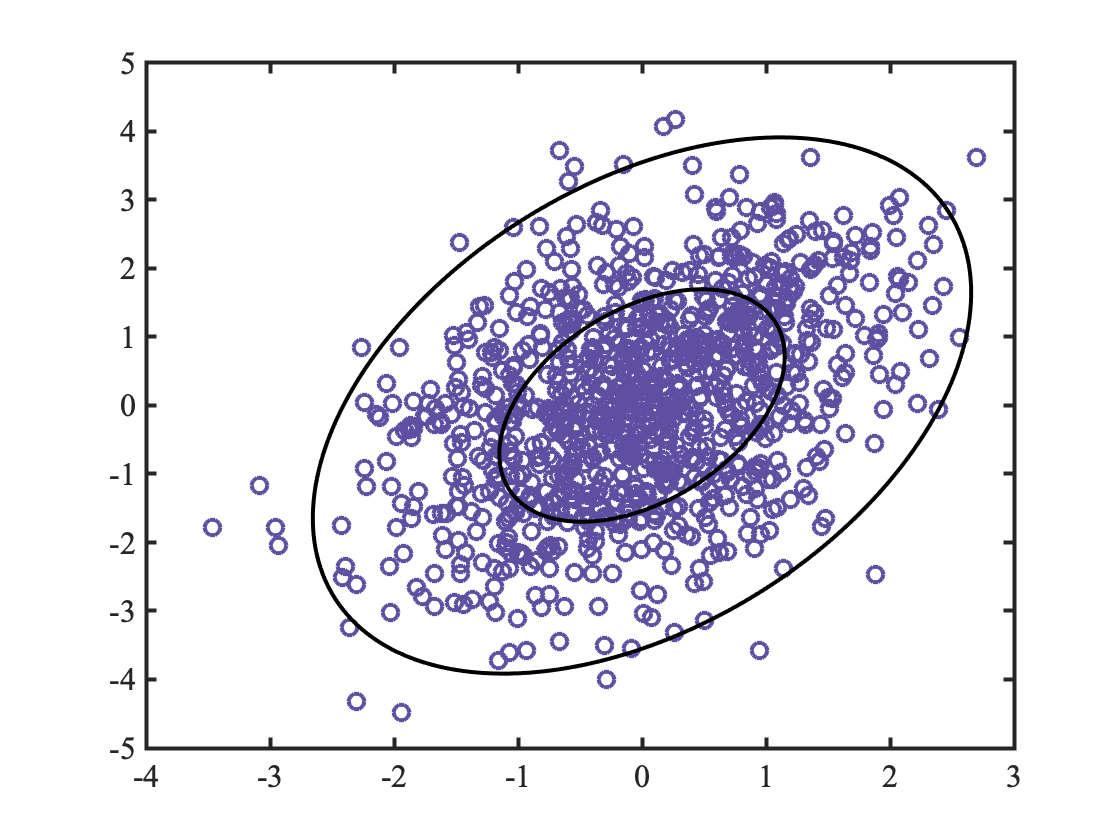

figure();
plot(binorm(:,1), binorm(:,2), 'o', 'markersize', 8);
hold on 
covArray = cov(binorm);
h = error_ellipse(covArray, my_mu1, 'conf', 0.5);
set(h, 'color', 'k')
h = error_ellipse(covArray, my_mu1, 'conf', 0.975);
set(h, 'color', 'k')
auto_save('confidEllipse')

## Local functions

function [H, pValue, W] = swtest(x, alpha)
% From https://www.mathworks.com/matlabcentral/fileexchange/13964-shapiro-wilk-and-shapiro-francia-normality-tests
%SWTEST Shapiro-Wilk parametric hypothesis test of composite normality.
%   [H, pValue, SWstatistic] = SWTEST(X, ALPHA) performs the
%   Shapiro-Wilk test to determine if the null hypothesis of
%   composite normality is a reasonable assumption regarding the
%   population distribution of a random sample X. The desired significance 
%   level, ALPHA, is an optional scalar input (default = 0.05).
%
%   The Shapiro-Wilk and Shapiro-Francia null hypothesis is: 
%   "X is normal with unspecified mean and variance."
%
%   This is an omnibus test, and is generally considered relatively
%   powerful against a variety of alternatives.
%   Shapiro-Wilk test is better than the Shapiro-Francia test for
%   Platykurtic sample. Conversely, Shapiro-Francia test is better than the
%   Shapiro-Wilk test for Leptokurtic samples.
%
%   When the series 'X' is Leptokurtic, SWTEST performs the Shapiro-Francia
%   test, else (series 'X' is Platykurtic) SWTEST performs the
%   Shapiro-Wilk test.
% 
%    [H, pValue, SWstatistic] = SWTEST(X, ALPHA)
%
% Inputs:
%   X - a vector of deviates from an unknown distribution. The observation
%     number must exceed 3 and less than 5000.
%
% Optional inputs:
%   ALPHA - The significance level for the test (default = 0.05).
%  
% Outputs:
%  SWstatistic - The test statistic (non normalized).
%
%   pValue - is the p-value, or the probability of observing the given
%     result by chance given that the null hypothesis is true. Small values
%     of pValue cast doubt on the validity of the null hypothesis.
%
%     H = 0 => Do not reject the null hypothesis at significance level ALPHA.
%     H = 1 => Reject the null hypothesis at significance level ALPHA.
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                Copyright (c) 17 March 2009 by Ahmed Ben Saïda          %
%                 Department of Finance, IHEC Sousse - Tunisia           %
%                       Email: ahmedbensaida@yahoo.com                   %
%                    $ Revision 3.0 $ Date: 18 Juin 2014 $               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% References:
%
% - Royston P. "Remark AS R94", Applied Statistics (1995), Vol. 44,
%   No. 4, pp. 547-551.
%   AS R94 -- calculates Shapiro-Wilk normality test and P-value
%   for sample sizes 3 <= n <= 5000. Handles censored or uncensored data.
%   Corrects AS 181, which was found to be inaccurate for n > 50.
%   Subroutine can be found at: http://lib.stat.cmu.edu/apstat/R94
%
% - Royston P. "A pocket-calculator algorithm for the Shapiro-Francia test
%   for non-normality: An application to medicine", Statistics in Medecine
%   (1993a), Vol. 12, pp. 181-184.
%
% - Royston P. "A Toolkit for Testing Non-Normality in Complete and
%   Censored Samples", Journal of the Royal Statistical Society Series D
%   (1993b), Vol. 42, No. 1, pp. 37-43.
%
% - Royston P. "Approximating the Shapiro-Wilk W-test for non-normality",
%   Statistics and Computing (1992), Vol. 2, pp. 117-119.
%
% - Royston P. "An Extension of Shapiro and Wilk's W Test for Normality
%   to Large Samples", Journal of the Royal Statistical Society Series C
%   (1982a), Vol. 31, No. 2, pp. 115-124.
%
%
% Ensure the sample data is a VECTOR.
%
if numel(x) == length(x)
    x  =  x(:);               % Ensure a column vector.
else
    error(' Input sample ''X'' must be a vector.');
end
%
% Remove missing observations indicated by NaN's and check sample size.
%
x  =  x(~isnan(x));
if length(x) < 3
   error(' Sample vector ''X'' must have at least 3 valid observations.');
end
if length(x) > 5000
    warning('Shapiro-Wilk test might be inaccurate due to large sample size ( > 5000).');
end
%
% Ensure the significance level, ALPHA, is a 
% scalar, and set default if necessary.
%
if (nargin >= 2) && ~isempty(alpha)
   if ~isscalar(alpha)
      error(' Significance level ''Alpha'' must be a scalar.');
   end
   if (alpha <= 0 || alpha >= 1)
      error(' Significance level ''Alpha'' must be between 0 and 1.'); 
   end
else
   alpha  =  0.05;
end
% First, calculate the a's for weights as a function of the m's
% See Royston (1992, p. 117) and Royston (1993b, p. 38) for details
% in the approximation.
x       =   sort(x); % Sort the vector X in ascending order.
n       =   length(x);
mtilde  =   norminv(((1:n)' - 3/8) / (n + 1/4));
weights =   zeros(n,1); % Preallocate the weights.
if kurtosis(x) > 3
    
    % The Shapiro-Francia test is better for leptokurtic samples.
    
    weights =   1/sqrt(mtilde'*mtilde) * mtilde;
    %
    % The Shapiro-Francia statistic W' is calculated to avoid excessive
    % rounding errors for W' close to 1 (a potential problem in very
    % large samples).
    %
    W   =   (weights' * x)^2 / ((x - mean(x))' * (x - mean(x)));
    % Royston (1993a, p. 183):
    nu      =   log(n);
    u1      =   log(nu) - nu;
    u2      =   log(nu) + 2/nu;
    mu      =   -1.2725 + (1.0521 * u1);
    sigma   =   1.0308 - (0.26758 * u2);
    newSFstatistic  =   log(1 - W);
    %
    % Compute the normalized Shapiro-Francia statistic and its p-value.
    %
    NormalSFstatistic =   (newSFstatistic - mu) / sigma;
    
    % Computes the p-value, Royston (1993a, p. 183).
    pValue   =   1 - normcdf(NormalSFstatistic, 0, 1);
    
else
    
    % The Shapiro-Wilk test is better for platykurtic samples.
    c    =   1/sqrt(mtilde'*mtilde) * mtilde;
    u    =   1/sqrt(n);
    % Royston (1992, p. 117) and Royston (1993b, p. 38):
    PolyCoef_1   =   [-2.706056 , 4.434685 , -2.071190 , -0.147981 , 0.221157 , c(n)];
    PolyCoef_2   =   [-3.582633 , 5.682633 , -1.752461 , -0.293762 , 0.042981 , c(n-1)];
    % Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1)
    PolyCoef_3   =   [-0.0006714 , 0.0250540 , -0.39978 , 0.54400];
    PolyCoef_4   =   [-0.0020322 , 0.0627670 , -0.77857 , 1.38220];
    PolyCoef_5   =   [0.00389150 , -0.083751 , -0.31082 , -1.5861];
    PolyCoef_6   =   [0.00303020 , -0.082676 , -0.48030];
    PolyCoef_7   =   [0.459 , -2.273];
    weights(n)   =   polyval(PolyCoef_1 , u);
    weights(1)   =   -weights(n);
    
    if n > 5
        weights(n-1) =   polyval(PolyCoef_2 , u);
        weights(2)   =   -weights(n-1);
    
        count  =   3;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2 - 2 * mtilde(n-1)^2) / ...
                (1 - 2 * weights(n)^2 - 2 * weights(n-1)^2);
    else
        count  =   2;
        phi    =   (mtilde'*mtilde - 2 * mtilde(n)^2) / ...
                (1 - 2 * weights(n)^2);
    end
        
    % Special attention when n = 3 (this is a special case).
    if n == 3
        % Royston (1992, p. 117)
        weights(1)  =   1/sqrt(2);
        weights(n)  =   -weights(1);
        phi = 1;
    end
    %
    % The vector 'WEIGHTS' obtained next corresponds to the same coefficients
    % listed by Shapiro-Wilk in their original test for small samples.
    %
    weights(count : n-count+1)  =  mtilde(count : n-count+1) / sqrt(phi);
    %
    % The Shapiro-Wilk statistic W is calculated to avoid excessive rounding
    % errors for W close to 1 (a potential problem in very large samples).
    %
    W   =   (weights' * x) ^2 / ((x - mean(x))' * (x - mean(x)));
    %
    % Calculate the normalized W and its significance level (exact for
    % n = 3). Royston (1992, p. 118) and Royston (1993b, p. 40, Table 1).
    %
    newn    =   log(n);
    if (n >= 4) && (n <= 11)
    
        mu      =   polyval(PolyCoef_3 , n);
        sigma   =   exp(polyval(PolyCoef_4 , n));    
        gam     =   polyval(PolyCoef_7 , n);
    
        newSWstatistic  =   -log(gam-log(1-W));
    
    elseif n > 11
    
        mu      =   polyval(PolyCoef_5 , newn);
        sigma   =   exp(polyval(PolyCoef_6 , newn));
    
        newSWstatistic  =   log(1 - W);
    
    elseif n == 3
        mu      =   0;
        sigma   =   1;
        newSWstatistic  =   0;
    end
    %
    % Compute the normalized Shapiro-Wilk statistic and its p-value.
    %
    NormalSWstatistic   =   (newSWstatistic - mu) / sigma;
    
    % NormalSWstatistic is referred to the upper tail of N(0,1),
    % Royston (1992, p. 119).
    pValue       =   1 - normcdf(NormalSWstatistic, 0, 1);
    
    % Special attention when n = 3 (this is a special case).
    if n == 3
        pValue  =   6/pi * (asin(sqrt(W)) - asin(sqrt(3/4)));
        % Royston (1982a, p. 121)
    end
    
end
%
% To maintain consistency with existing Statistics Toolbox hypothesis
% tests, returning 'H = 0' implies that we 'Do not reject the null 
% hypothesis at the significance level of alpha' and 'H = 1' implies 
% that we 'Reject the null hypothesis at significance level of alpha.'
%
H  = (alpha >= pValue);
end

function h=error_ellipse(varargin)
% ERROR_ELLIPSE - plot an error ellipse, or ellipsoid, defining confidence region
%    ERROR_ELLIPSE(C22) - Given a 2x2 covariance matrix, plot the
%    associated error ellipse, at the origin. It returns a graphics handle
%    of the ellipse that was drawn.
%
%    ERROR_ELLIPSE(C33) - Given a 3x3 covariance matrix, plot the
%    associated error ellipsoid, at the origin, as well as its projections
%    onto the three axes. Returns a vector of 4 graphics handles, for the
%    three ellipses (in the X-Y, Y-Z, and Z-X planes, respectively) and for
%    the ellipsoid.
%
%    ERROR_ELLIPSE(C,MU) - Plot the ellipse, or ellipsoid, centered at MU,
%    a vector whose length should match that of C (which is 2x2 or 3x3).
%
%    ERROR_ELLIPSE(...,'Property1',Value1,'Name2',Value2,...) sets the
%    values of specified properties, including:
%      'C' - Alternate method of specifying the covariance matrix
%      'mu' - Alternate method of specifying the ellipse (-oid) center
%      'conf' - A value betwen 0 and 1 specifying the confidence interval.
%        the default is 0.5 which is the 50% error ellipse.
%      'scale' - Allow the plot the be scaled to difference units.
%      'style' - A plotting style used to format ellipses.
%      'clip' - specifies a clipping radius. Portions of the ellipse, -oid,
%        outside the radius will not be shown.
%
%    NOTES: C must be positive definite for this function to work properly.
default_properties = struct(...
  'C', [], ... % The covaraince matrix (required)
  'mu', [], ... % Center of ellipse (optional)
  'conf', 0.5, ... % Percent confidence/100
  'scale', 1, ... % Scale factor, e.g. 1e-3 to plot m as km
  'style', '', ...  % Plot style
  'clip', inf); % Clipping radius
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.C = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.mu = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.conf = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & isnumeric(varargin{1})
  default_properties.scale = varargin{1};
  varargin(1) = [];
end
if length(varargin) >= 1 & ~ischar(varargin{1})
  error('Invalid parameter/value pair arguments.') 
end
prop = getopt(default_properties, varargin{:});
C = prop.C;
if isempty(prop.mu)
  mu = zeros(length(C),1);
else
  mu = prop.mu;
end
conf = prop.conf;
scale = prop.scale;
style = prop.style;
if conf <= 0 | conf >= 1
  error('conf parameter must be in range 0 to 1, exclusive')
end
[r,c] = size(C);
if r ~= c | (r ~= 2 & r ~= 3)
  error(['Don''t know what to do with ',num2str(r),'x',num2str(c),' matrix'])
end
x0=mu(1);
y0=mu(2);
% Compute quantile for the desired percentile
k = sqrt(qchisq(conf,r)); % r is the number of dimensions (degrees of freedom)
hold_state = get(gca,'nextplot');
if r==3 & c==3
  z0=mu(3);
  
  % Make the matrix has positive eigenvalues - else it's not a valid covariance matrix!
  if any(eig(C) <=0)
    error('The covariance matrix must be positive definite (it has non-positive eigenvalues)')
  end
  % C is 3x3; extract the 2x2 matricies, and plot the associated error
  % ellipses. They are drawn in space, around the ellipsoid; it may be
  % preferable to draw them on the axes.
  Cxy = C(1:2,1:2);
  Cyz = C(2:3,2:3);
  Czx = C([3 1],[3 1]);
  [x,y,z] = getpoints(Cxy,prop.clip);
  h1=plot3(x0+k*x,y0+k*y,z0+k*z,prop.style);hold on
  [y,z,x] = getpoints(Cyz,prop.clip);
  h2=plot3(x0+k*x,y0+k*y,z0+k*z,prop.style);hold on
  [z,x,y] = getpoints(Czx,prop.clip);
  h3=plot3(x0+k*x,y0+k*y,z0+k*z,prop.style);hold on
  
  [eigvec,eigval] = eig(C);
  [X,Y,Z] = ellipsoid(0,0,0,1,1,1);
  XYZ = [X(:),Y(:),Z(:)]*sqrt(eigval)*eigvec';
  
  X(:) = scale*(k*XYZ(:,1)+x0);
  Y(:) = scale*(k*XYZ(:,2)+y0);
  Z(:) = scale*(k*XYZ(:,3)+z0);
  h4=surf(X,Y,Z);
  colormap gray
  alpha(0.3)
  camlight
  if nargout
    h=[h1 h2 h3 h4];
  end
elseif r==2 & c==2
  % Make the matrix has positive eigenvalues - else it's not a valid covariance matrix!
  if any(eig(C) <=0)
    error('The covariance matrix must be positive definite (it has non-positive eigenvalues)')
  end
  [x,y,z] = getpoints(C,prop.clip);
  h1=plot(scale*(x0+k*x),scale*(y0+k*y),prop.style);
  set(h1,'zdata',z+1)
  if nargout
    h=h1;
  end
else
  error('C (covaraince matrix) must be specified as a 2x2 or 3x3 matrix)')
end
%axis equal
set(gca,'nextplot',hold_state);
%---------------------------------------------------------------
% getpoints - Generate x and y points that define an ellipse, given a 2x2
%   covariance matrix, C. z, if requested, is all zeros with same shape as
%   x and y.
end
function [x,y,z] = getpoints(C,clipping_radius)
n=100; % Number of points around ellipse
p=0:pi/n:2*pi; % angles around a circle
[eigvec,eigval] = eig(C); % Compute eigen-stuff
xy = [cos(p'),sin(p')] * sqrt(eigval) * eigvec'; % Transformation
x = xy(:,1);
y = xy(:,2);
z = zeros(size(x));
% Clip data to a bounding radius
if nargin >= 2
  r = sqrt(sum(xy.^2,2)); % Euclidian distance (distance from center)
  x(r > clipping_radius) = nan;
  y(r > clipping_radius) = nan;
  z(r > clipping_radius) = nan;
end
end
%---------------------------------------------------------------
function x=qchisq(P,n)
% QCHISQ(P,N) - quantile of the chi-square distribution.
if nargin<2
  n=1;
end
s0 = P==0;
s1 = P==1;
s = P>0 & P<1;
x = 0.5*ones(size(P));
x(s0) = -inf;
x(s1) = inf;
x(~(s0|s1|s))=nan;
for ii=1:14
  dx = -(pchisq(x(s),n)-P(s))./dchisq(x(s),n);
  x(s) = x(s)+dx;
  if all(abs(dx) < 1e-6)
    break;
  end
end
end
%---------------------------------------------------------------
function F=pchisq(x,n)
% PCHISQ(X,N) - Probability function of the chi-square distribution.
if nargin<2
  n=1;
end
F=zeros(size(x));
if rem(n,2) == 0
  s = x>0;
  k = 0;
  for jj = 0:n/2-1;
    k = k + (x(s)/2).^jj/factorial(jj);
  end
  F(s) = 1-exp(-x(s)/2).*k;
else
  for ii=1:numel(x)
    if x(ii) > 0
      F(ii) = quadl(@dchisq,0,x(ii),1e-6,0,n);
    else
      F(ii) = 0;
    end
  end
end
end
%---------------------------------------------------------------
function f=dchisq(x,n)
% DCHISQ(X,N) - Density function of the chi-square distribution.
if nargin<2
  n=1;
end
f=zeros(size(x));
s = x>=0;
f(s) = x(s).^(n/2-1).*exp(-x(s)/2)./(2^(n/2)*gamma(n/2));
end
%---------------------------------------------------------------
function properties = getopt(properties,varargin)
%GETOPT - Process paired optional arguments as 'prop1',val1,'prop2',val2,...
%
%   getopt(properties,varargin) returns a modified properties structure,
%   given an initial properties structure, and a list of paired arguments.
%   Each argumnet pair should be of the form property_name,val where
%   property_name is the name of one of the field in properties, and val is
%   the value to be assigned to that structure field.
%
%   No validation of the values is performed.
%
% EXAMPLE:
%   properties = struct('zoom',1.0,'aspect',1.0,'gamma',1.0,'file',[],'bg',[]);
%   properties = getopt(properties,'aspect',0.76,'file','mydata.dat')
% would return:
%   properties = 
%         zoom: 1
%       aspect: 0.7600
%        gamma: 1
%         file: 'mydata.dat'
%           bg: []
%
% Typical usage in a function:
%   properties = getopt(properties,varargin{:})
% Process the properties (optional input arguments)
prop_names = fieldnames(properties);
TargetField = [];
for ii=1:length(varargin)
  arg = varargin{ii};
  if isempty(TargetField)
    if ~ischar(arg)
      error('Propery names must be character strings');
    end
    f = find(strcmp(prop_names, arg));
    if length(f) == 0
      error('%s ',['invalid property ''',arg,'''; must be one of:'],prop_names{:});
    end
    TargetField = arg;
  else
    % properties.(TargetField) = arg; % Ver 6.5 and later only
    properties = setfield(properties, TargetField, arg); % Ver 6.1 friendly
    TargetField = '';
  end
end
if ~isempty(TargetField)
  error('Property names and values must be specified in pairs.');
end
end